# 4주차 과제 — 시간응답

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 공식과 실측을 나란히 비교

- **2. 기본** (중간 · 40분 · 70점) — 사양을 주면 극점을 찾아내기

- **3. 도전** (선택 · 가산점 10점) — 극점이 셋이면 공식이 언제 틀리나

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

clc; close all;
s = tf('s');

## 1. 몸풀기 — 공식이 정말 맞나

**강의노트 4-1절과 4-2절을 그대로 보면 됩니다.**

오늘 재는 것은 아래 그림에서 $y(t)$ 의 **모양**입니다.

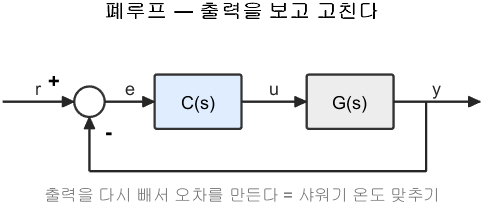

폐루프 — 출력을 보고 고친다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

## 1-0. 공식 두 개

2차 표준형은 이렇게 생겼습니다.


$$G(s) = \frac{\omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2}$$


그리고 배운 공식 두 개는 이것입니다.


$$\%OS = 100\,e^{-\pi\zeta/\sqrt{1-\zeta^2}}, \qquad t_s \approx \frac{4}{\zeta\omega_n}$$


할 일

- $\omega_n = 2$ 로 고정하고 $\zeta$ 만 바꿔 가며 표를 채우십시오

- `TODO` 두 줄만 채우면 됩니다

맞았는지 확인하는 법

- 공식과 실측이 오버슈트는 거의 같고, 정착시간은 조금 다릅니다

- 정착시간이 왜 다른지는 아래에서 설명합니다

wn = 2;
zeta_list = [0.2 0.4 0.6 0.8];

fprintf('  zeta   OS(공식)[%%]  OS(실측)[%%]  ts(공식)[s]  ts(실측)[s]\n');
fprintf('  ----  -----------  -----------  -----------  -----------\n');
for z = zeta_list
    G = wn^2/(s^2 + 2*z*wn*s + wn^2);
    os_f = NaN;   % TODO : 위 공식으로 오버슈트를 계산하십시오
    ts_f = 4/(z*wn);
    info = stepinfo(G);
    os_m = NaN;   % TODO : stepinfo 결과에서 오버슈트를 꺼내십시오
    fprintf('  %4.1f  %11.2f  %11.2f  %11.3f  %11.3f\n', ...
            z, os_f, os_m, ts_f, info.SettlingTime);
end

## 1-1. 그림으로 보기

코드는 다 되어 있습니다.

t1 = (0:0.02:12)';
tiledlayout(1,2,'TileSpacing','compact');

nexttile
hold on; grid on;
for z = zeta_list
    plot(t1, step(wn^2/(s^2 + 2*z*wn*s + wn^2), t1), 'LineWidth', 2, ...
         'DisplayName', sprintf('\\zeta = %.1f', z));
end
yline(1, 'k--', 'HandleVisibility', 'off');
yline(1.02, 'k:', 'HandleVisibility', 'off');
yline(0.98, 'k:', 'HandleVisibility', 'off');
xlabel('시간 [s]'); ylabel('출력');
title('감쇠비가 작을수록 많이 튄다');
legend('Location','southeast');

nexttile
hold on; grid on;
for z = zeta_list
    pl = pole(wn^2/(s^2 + 2*z*wn*s + wn^2));
    plot(real(pl), imag(pl), 'x', 'MarkerSize', 12, 'LineWidth', 2, ...
         'DisplayName', sprintf('\\zeta = %.1f', z));
end
xline(0,'k-','HandleVisibility','off'); yline(0,'k-','HandleVisibility','off');
xlabel('실수부'); ylabel('허수부'); axis equal;
title('그때 극점은 여기에 있다');
legend('Location','best');

## 1-2. 답할 것 (두 문장이면 됩니다)

- 오버슈트는 $\zeta$ 만으로 정해지는가, $\omega_n$ 도 필요한가?

- 정착시간 공식과 실측이 조금 다릅니다. 왜 그럴지 한 줄로 추측해 보십시오 (힌트 : 위 그림에서 응답이 $\pm 2\%$ 띠를 몇 번 들락날락하는지 보십시오)

## 2. 기본 — 사양을 주면 극점을 찾아내기

**강의노트 4-3절과 5절을 그대로 보면 됩니다.**

이번에는 반대로 갑니다. 원하는 성능을 먼저 정하고, 그런 응답을 내는 **극점이 어디여야 하는지**를 구합니다. 이것이 설계의 출발점입니다.

요구 사양

- 오버슈트 $\le 10\%$

- 정착시간 $\le 2$ 초

할 일 — 세 단계입니다.

## 2-1. 1단계 : 사양을 $\zeta$ 와 $\omega_n$ 으로

`spec2pole` 이 두 공식을 뒤집어 계산해 줍니다.

- **입력** 오버슈트 [%] 와 정착시간 [s]

- **출력** `[zeta_min, wn_min, s_target]`

- `s_target` 은 그 두 조건을 **딱 맞게** 만족하는 극점입니다

실행만 하면 됩니다.

P_OS = 10;  ts = 2;
[zmin, wmin, starget] = spec2pole(P_OS, ts);

fprintf('\n=== 사양 변환 ===\n');
fprintf('  요구 : 오버슈트 %.0f %% 이하, 정착시간 %.0f s 이하\n', P_OS, ts);
fprintf('  -> zeta >= %.4f , wn >= %.4f\n', zmin, wmin);
fprintf('  -> 목표 극점 : %+.3f %+.3fj\n', real(starget), imag(starget));

## 2-2. 2단계 : 그 극점을 갖는 시스템 만들기

목표 극점이 $-\sigma \pm j\omega_d$ 라면 분모는 이렇게 됩니다.


$$s^2 + 2\sigma s + (\sigma^2 + \omega_d^2)$$


`TODO` 한 줄만 채우십시오.

힌트 : `poly([starget, conj(starget)])` 를 쓰면 분모 계수가 바로 나옵니다.

den_ = NaN;    % TODO : poly([starget, conj(starget)]) 로 분모 계수를 구하십시오

if ~any(isnan(den_))
    G2 = tf(den_(end), den_);         % DC 이득이 1 이 되도록 분자를 맞춘다
    fprintf('\n설계한 시스템\n'); G2
    fprintf('  극점 : %s\n', mat2str(round(pole(G2).', 3)));
end

## 2-3. 3단계 : 검증

만든 시스템이 정말 사양을 만족하는지 `stepinfo` 로 확인합니다. 코드는 다 되어 있습니다.

if exist('G2', 'var') && isa(G2, 'tf')
    i2 = stepinfo(G2);
    fprintf('\n=== 검증 ===\n');
    fprintf('  오버슈트 %.2f %%  (요구 %.0f 이하)  -> %s\n', ...
            i2.Overshoot, P_OS, string(i2.Overshoot <= P_OS + 0.5));
    fprintf('  정착시간 %.3f s   (요구 %.0f 이하)  -> %s\n', ...
            i2.SettlingTime, ts, string(i2.SettlingTime <= ts + 0.1));

    t2 = (0:0.01:4)';
    figure;
    plot(t2, step(G2, t2), 'LineWidth', 2); hold on;
    yline(1, 'k--'); yline(1 + P_OS/100, 'r:', 'LineWidth', 1.5);
    xline(ts, 'r:', 'LineWidth', 1.5);
    grid on; xlabel('시간 [s]'); ylabel('출력');
    legend('설계 결과', '목표', '오버슈트 한계', '정착시간 한계', 'Location', 'southeast');
    title('사양에서 출발해 만든 시스템');
end

## 2-4. 답할 것 (세 문장이면 됩니다)

- 목표 극점의 **실수부**는 어느 사양이 정하는가?

- 목표 극점의 **각도**(원점에서 본)는 어느 사양이 정하는가?

- 정착시간 요구를 $2$ 초에서 $1$ 초로 줄이면 극점은 어느 쪽으로 옮겨야 하는가?

## 3. 도전 (선택) — 극점이 셋이면 공식이 언제 틀리나

**이 문제는 선택입니다. 안 해도 만점입니다.** 가산점 10점입니다.

지금까지 쓴 공식은 **극점이 딱 두 개**일 때 만든 것입니다. 실제 시스템은 극점이 더 많습니다. 그러면 공식이 언제부터 맞지 않는가?

2번에서 만든 2차 시스템에 극점을 하나 더 붙입니다.


$$G_3(s) = G_2(s)\cdot\frac{p}{s+p}$$


할 일

- $p$ 를 $\sigma$ 의 $1, 2, 5, 10$ 배로 바꿔 가며 `stepinfo` 를 재라 ($\sigma$ 는 2번에서 구한 목표 극점의 실수부 크기입니다)

- 오버슈트와 정착시간이 2차 때와 얼마나 달라지는지 표로 적어라

답할 것 (한 문장)

- 세 번째 극점을 **몇 배쯤** 멀리 두면 2차 공식을 믿어도 되겠는가? (실무에서는 보통 5배를 기준으로 씁니다. 표에서 확인해 보십시오)

TODO : 여기에 코드를 작성하십시오

## 채점 기준

- **1. 몸풀기** 30점 — 표를 채웠는가, 두 질문에 답했는가

- **2. 기본** 70점 — 세 단계와 검증, 세 질문에 답했는가

- **3. 도전** 가산점 10점

감점 사항 (세 가지뿐입니다)

- 축 이름이나 범례가 없는 그림

- 숫자만 있고 설명이 한 줄도 없는 경우

- 코드가 오류로 멈추는 경우